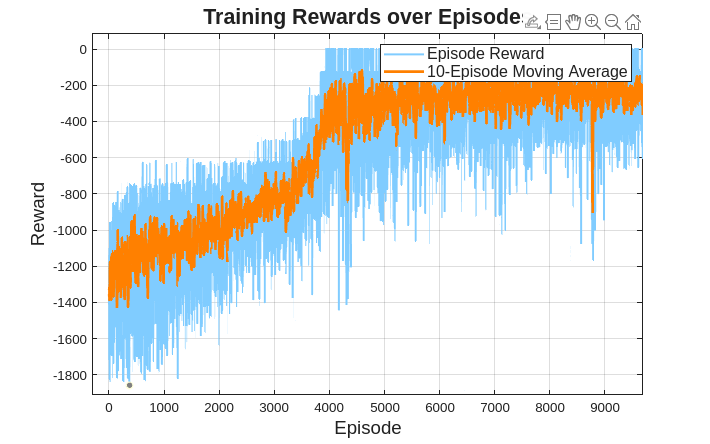

rewards = load('./weights/pendulum_epi_reward.txt');
num_episodes = length(rewards);

window = 10;
moving_avg = movmean(rewards, window);

figure('Position', [1000, 300, 800, 500]);

plot(rewards, 'Color', [0.5 0.8 1], 'LineWidth', 1.5); hold on;
plot(moving_avg, 'Color', [1 0.5 0], 'LineWidth', 2);

title('Training Rewards over Episodes', 'FontSize', 16);
xlabel('Episode', 'FontSize', 14);
ylabel('Reward', 'FontSize', 14);
legend('Episode Reward', sprintf('%d-Episode Moving Average', window), 'FontSize', 12);
grid on;


%% 💾 Save figure as image (optional)
% saveas(gcf, './weights/reward_plot.png');
% saveas(gcf, './weights/reward_plot.pdf');